# `MATH 3620 Numerical Analysis`

# `Homework 5`

# `03 May 2021`

close all; clear all ; clc;

## `Q1. Trigonometric Polynomial Interpolation and FFT`

## `1b`

% parameters
N = 8;
j = 0:N-1;
xj = j*(2*pi/N);

% function to be interpolated
f = [6, 10.242640687119284, 2, -2.585786437626905, 2, 1.757359312880716, -6, -5.414213562373098];

% for testing purposes (use without aNby2)
% x = [0:7]/8;
% f = sin(2*pi*x) + cos(2*pi*x) + 0.25

% get Fourier coefficients
[a, b] = TrigInterpolate(f);
aNby2 = (2/N)*sum(f.*cos((N/2)*xj));

% define interpolating trig polynomial (works only for a single value of x)
k = 1:(N/2) - 1;
P = @(x) a(1)/2 + sum(a(2:end).*cos(k*x)) + sum(b(1:end).*sin(k*x)) + (aNby2/2)*cos((N/2)*x); 

% check if P(x) is defined correctly 
[P(xj(4)) - f(4), P(xj(5)) - f(5)] % ans = 0

ans = 	1.0e+-15 *

   -0.4441   -0.8882


`The polynomial `$p_N(x)$ `has been defined as an anonymous function. Evaluating the polynomial at the nodes and comparing it with the function value reveals that the polynomial has been setup correctly.`

% print interpolating polynomial
syms x
p = a(1)/2 + sum(a(2:end).*cos(k*x)) + sum(b(1:end).*sin(k*x)) + (aNby2/2)*cos((N/2)*x);
p_N = vpa(p, 6)

$$p\_N = 3.0\,\cos\left(2.0\,x\right)+3.33067e-16\,\cos\left(4.0\,x\right)+5.0\,\sin\left(2.0\,x\right)+7.77156e-16\,\cos\left(3.0\,x\right)+2.0\,\cos\left(x\right)+4.0\,\sin\left(x\right)+1.0$$

## `Q2. Spectral Derivative Approximation`

% parameters
N = 8;
j = 0:N-1;
xj = j*(2*pi/N);

% function to be interpolated
f = exp(sin(xj));

% get Fourier coefficients
[a, b] = TrigInterpolate(f);
aNby2 = (2/N)*sum(f.*cos((N/2)*xj));

% define interpolating trig polynomial (works only for a single value of x)
k = 1:(N/2) - 1;
P = @(x) a(1)/2 + sum(a(2:end).*cos(k*x)) + sum(b(1:end).*sin(k*x)) + (aNby2/2)*cos((N/2)*x); 

% check if P(x) is defined correctly 
[P(xj(4)) - f(4), P(xj(5)) - f(5)] % ans = 0

ans =      0     0


% print interpolating polynomial
syms x
p = a(1)/2 + sum(a(2:end).*cos(k*x)) + sum(b(1:end).*sin(k*x)) + (aNby2/2)*cos((N/2)*x);
p_N = vpa(p, 6)

$$p\_N = 0.00547424\,\cos\left(4.0\,x\right)-0.27154\,\cos\left(2.0\,x\right)-1.11022e-16\,\sin\left(2.0\,x\right)+2.29935e-17\,\cos\left(3.0\,x\right)-0.0448798\,\sin\left(3.0\,x\right)-1.34016e-16\,\cos\left(x\right)+1.13032\,\sin\left(x\right)+1.26607$$

% spectral approximation of derivative
dpdx = diff(p, x);
% evaluate at x_j
approx_deriv = double(subs(dpdx, xj));
% compute error in approximation
df = exp(sin(xj)).*cos(xj);
e = abs(approx_deriv - df)

e =     0.0043    0.0034    0.0000    0.0034    0.0043    0.0027    0.0000    0.0027


`The asbolute values of errors in the approximation are printed above.`

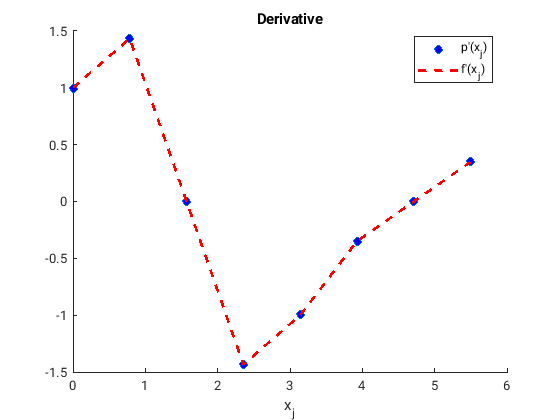

% make plots
scatter(xj, approx_deriv, 40, 'MarkerFaceColor','blue')
hold on
plot(xj, df, 'r--', 'LineWidth', 2)
xlabel('x_j')
legend('p''(x_j)', 'f''(x_j)', 'location', 'best')
title('Derivative')
hold off

## `Q3. Spectral Derivative Approximation using DFT and Inverse DFT`

## `3b`

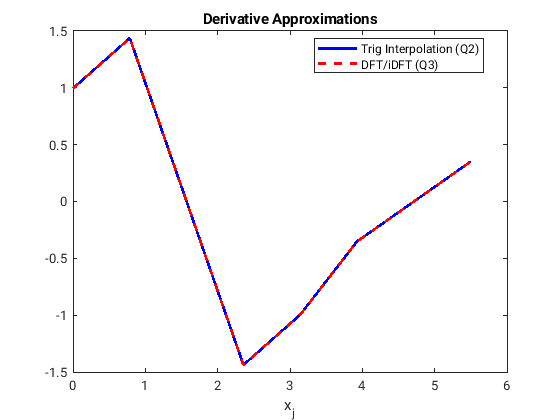

% parameters
N = 8;
j = 0:N-1;
xj = j*(2*pi/N);

% function
f = exp(sin(xj));

% spectral derivative approximation
fp = spectralDeriv(f);
fp = real(fp); % ignore imaginary part

% compare with ans from Q2
plot(xj, approx_deriv, 'b-', 'LineWidth', 2)
hold on
plot(xj, real(fp), 'r--', 'LineWidth', 2)
xlabel('x_j')
legend('Trig Interpolation (Q2)', 'DFT/iDFT (Q3)', 'location', 'best')
hold off
title('Derivative Approximations')

% difference
dfp = abs(approx_deriv - real(fp))

dfp = 	1.0e+-14 *

    0.0555    0.0666    0.1234    0.0444    0.0333    0.0555    0.0201    0.1110


`From the plot and the difference values, we can see that the approximations are close to each other in value.`

## `3c`

% N = 8
fp8 = fp;
% compute error in approximation
df = exp(sin(xj)).*cos(xj);
e8 = abs(fp8 - df);

% N = 16
N = 16;
j = 0:N-1;
xj = j*(2*pi/N);
f = exp(sin(xj));
fp16 = spectralDeriv(f);
fp16 = real(fp16);
% compute error in approximation
df = exp(sin(xj)).*cos(xj);
e16 = abs(fp16 - df);

% N = 32
N = 16;
j = 0:N-1;
xj = j*(2*pi/N);
f = exp(sin(xj));
fp32 = spectralDeriv(f);
fp32 = real(fp32);
% compute error in approximation
df = exp(sin(xj)).*cos(xj);
e32 = abs(fp32 - df);

% plot rms value of error
e = [rms(e8), rms(e16), rms(e32)]

e =     0.0031    0.0000    0.0000


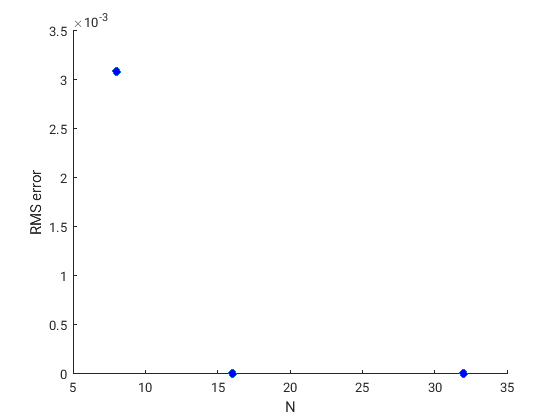

scatter([8 16 32], e, 40, 'MarkerFaceColor', 'blue')
xlabel('N')
ylabel('RMS error')

`We can see that as N is increased, the errors decay to zero. We get derivatives accurate to machine precision with N = 16 itself.`

## `Function Definitions`

## `1a`

function [a, b] = TrigInterpolate(f)
    % this function returns the real Fourier coefficients needed to define
    % p_N(x); does not provide aNby2
    
    c = fft(f);
    N = length(f);
    b = -imag(c)/(N/2);
    b = b(2:N/2);
    a = real(c)/(N/2);
    a = a(1:N/2);
end


## `3a`

function [fp] = spectralDeriv(f)
    % this function conputes the spectral derivative approximation to the
    % periodic array f
    
    % parameters
    N = length(f);
    j = 0:N-1;
    xj = j*(2*pi/N);
    
    % DFT
    c = zeros(1, N);
    k = 0;
    for i = 1:length(c)
        c(i) = (1/N)*sum(f.*exp(-1i*k*xj));
        k = k+1;
    end
    
    % rearrange c using periodicity
    c = [c(N/2+1:end), c(1:N/2)];
    % Fourier coefficients of derivative
    k = -N/2:(N/2-1);
    cp = 1i*k.*c;
    
    % rearrange coefficients again
    cp = [cp(N/2+1:end), cp(1:N/2)];
    
    % inverse DFT
    k = 0:N-1;
    fp = zeros(1, N);
    for i = 1:length(fp)
        fp(i) = sum(cp.*exp(1i*k*xj(i)));
    end
end